% generate figure 1E (two animals)
% dependence: initRSG2prior, v2struct, DnPlotResponses2P, HsHistTpOverlap, BLS

### set up

S=initRSG2prior;
v2struct(S); % behDir animalNm nAnimal

### main loop

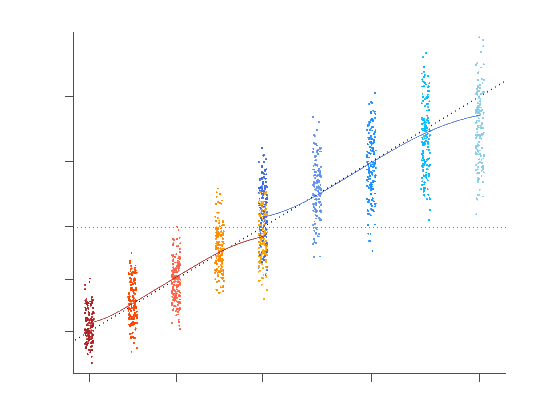

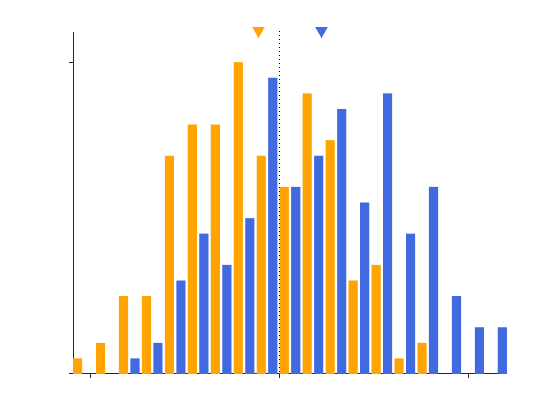

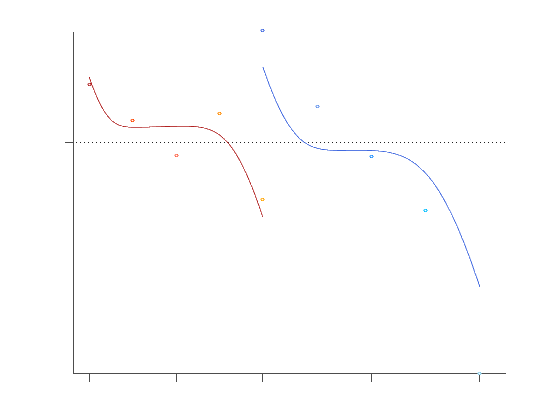

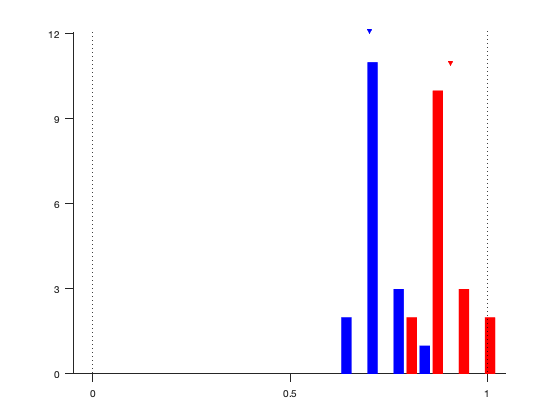

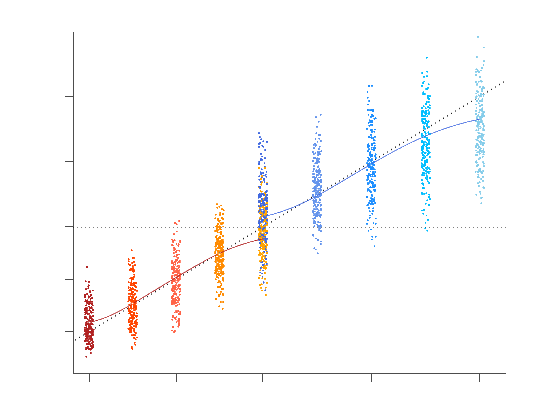

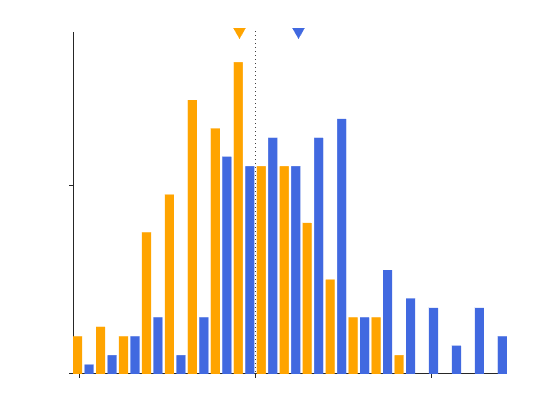

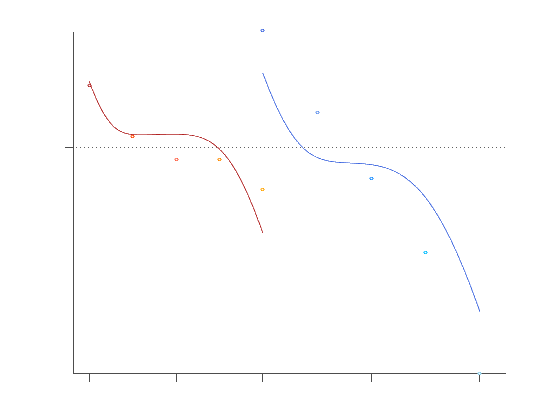

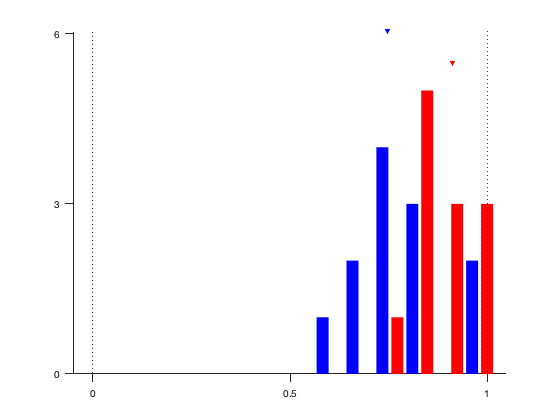

for i=1:nAnimal
    id=animalNm{i};
    tmp=load(fullfile(behDir,[ id '_RSGprior_DMFC.mat']));
    
    %  figure: tp vs ts + histogram at overlap ts
    if i==1 % H: SELECT BEST SESSION FOR VISUALIZATION
        tmp.iSess=161218;
    else % animal G
        tmp.iSess=170512;
    end
    plot_tp_ts(S,tmp);
    
    % figure: tp-ts vs ts
    plot_bias_prior(S,tmp);
    
    % figure: beta histogram
    plot_beta_histogram(S,tmp);
    
end

## subfunction for each animal

### figure: beta histogram

function plot_beta_histogram(S,tmp)

v2struct(S);
v2struct(tmp);

figure; hold all;
sessUni=unique(sessId);

% regression to get slope
slope=nan(nPr,nEH,length(sessUni));
sFull=nan(nPr,nEH,nTarg,length(sessUni)); % for all comb (pr, EH, targ)
for iSess=1:length(sessUni)
    % session data
    idSess=sessId==sessUni(iSess);
    ts=T(~idOut & idSess);
    tp=t(~idOut & idSess);
    ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
    citdx2=2-idHandEye(~idOut & idSess); % 1 for eye, 2 for hand
    citdx3=2-(theta(~idOut & idSess)==0); % 1 for right, 2 for left
    
    % weighted regression with precision of tp as weights
    % getting std(tp|ts)
    stp=nan(size(ts));
    stp2=nan(size(ts));
    for i=1:nPr
        for k=1:nTspp
            for j=1:nEH
                id=ctidx==i &... % idShortTrial
                    ts==Tmat{i}(k) &... % ts
                    citdx2==j;            % eye hand
                stp(id)=std(tp(id));
                for l=1:nTarg
                    id2=ctidx==i &... % idShortTrial
                        ts==Tmat{i}(k) &... % ts
                        citdx2==j &...            % eye hand
                        citdx3==l; % right left
                    stp2(id2)=std(tp(id2));
                end
            end
        end
    end
    for i=1:nPr
        for j=1:nEH
            id=ctidx==i &... % idShortTrial
                citdx2==j;            % eye hand
            LM=fitlm(ts(id),tp(id),'linear',...
                'Weights',1./stp(id));
            slope(i,j,iSess)=table2array(LM.Coefficients(2,1));
            
            for l=1:nTarg
                id2=ctidx==i &... % idShortTrial
                    citdx2==j &...            % eye hand
                    citdx3==l; % right left
                LM2=fitlm(ts(id2),tp(id2),'linear',...
                    'Weights',1./stp2(id2));
                sFull(i,j,l,iSess)=table2array(LM2.Coefficients(2,1));
            end % l targ
        end % j EH
    end % i Pr
    
end % iSess

% plotting spec
nBin=8;barWidth=0.4;markersize=4;
optsExpFig.Width=3; % 10/2.54;
optsExpFig.Height=3; % 7.3/2.54;

% summary for plot
x=squeeze(mean(mean(sFull(1,:,:,:),2),3)); % sessions by 1
y=squeeze(mean(mean(sFull(2,:,:,:),2),3));
b=linspace(min([x(:);y(:)]),max([x(:);y(:)]),nBin);

% plot
h=histogram(x,b); i=1; % short
Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
Xval    = Xval(1:end-1);Yval    = h.Values; delete(h);
hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',pplot.cmap{(i-1)*nPr+1},'EdgeColor','none');
axis tight; 
% plot mean
maxYlim=max(ylim);
plot(mean(x),1.1*maxYlim,'color',pplot.cmap{(i-1)*nPr+1},'markerfacecolor',pplot.cmap{(i-1)*nPr+1},'marker','v','markersize',markersize);

h=histogram(y,b); i=2; % long
Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
Xval    = Xval(1:end-1);Yval    = h.Values; delete(h);
hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',pplot.cmap{(i-1)*nPr+1},'EdgeColor','none');
axis tight; 
% plot mean
maxYlim=max(ylim);
plot(mean(y),1.1*maxYlim,'color',pplot.cmap{(i-1)*nPr+1},'markerfacecolor',pplot.cmap{(i-1)*nPr+1},'marker','v','markersize',markersize);

plotVertical(gca,0,[]); plotVertical(gca,1,[]);

xlim([-0.05 1.05]);
set(gca,'xtick',0:0.5:1,'ytick',0:3:20,'tickdir','out','ticklength',[0.02 0.02]);
pause(0.1);

end

### figure: tp vs ts

function plot_tp_ts(S,tmp)

idExpFig=0;

v2struct(S);
v2struct(tmp);

idExSess=1;
if idExSess
    idSess=sessId==iSess; % or 161205
else
    idSess=true(size(sessId));
end

d.ts=T(~idOut & idSess);
d.tp=t(~idOut & idSess);
ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
ipidx=nan(size(ctidx));

PlotDiff=0; % plot tp-ts?
% data formatting: [# interval x maxRepetition]
% find max # trials 1st
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial(~idOut & idSess)==(2-i) &... % idShortTrial
            d.ts==Tmat{i}(k); % ts
        if exist('nMaxTrial')
            nMaxTrial=max([nMaxTrial; nnz(id)]);
        else
            nMaxTrial=nnz(id);
        end
        ipidx(id)=k; % for each trial in d.ts specifies which time bin or ts interval it belongs to. Values: 1-5
    end
end
% filling matrix
Ts=nan(length(Tall),nMaxTrial); % [K x R]
Tp=nan(length(Tall),nMaxTrial);
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial(~idOut & idSess)==(2-i) &... % idShortTrial
            d.ts==Tmat{i}(k); % ts
        Ts((i-1)*nTspp+k,1:nnz(id))=d.ts(id);
        Tp((i-1)*nTspp+k,1:nnz(id))=d.tp(id);
    end
end
d.Ts=Ts;
d.Tp=Tp;
% theory
if idExSess
    idSessTmp=find(unique(sessId)==iSess);
    wm=wFitSess(idSessTmp).w_m;
    wp=wFitSess(idSessTmp).w_p;
    offset=[wFitSess(idSessTmp).offset2; wFitSess(idSessTmp).offset1];
else
    wm=wFit.w_m;
    wp=wFit.w_p;
    offset=[wFit.offset2; wFit.offset1];
end
for i=1:nPr
    theory{i}.tm=[min(Tmat{i}):max(Tmat{i})]'; % theory{x}.tm - Tx1 - sample corresponding to above
    theory{i}.te=BLS(theory{i}.tm,wm,[min(Tmat{i}) max(Tmat{i})],'uniform')+offset(i);theory{i}.te=theory{i}.te(:);
    theory{i}.range=1:length(theory{i}.tm);
    theory{i}.wm=wm;
end
DnPlotResponses2P(d,theory,ctidx,ipidx,PlotDiff); % PlotDiff for the last input

xlim([450 1250]);
set(gca,'xtick',[480 640 800 1000 1200],'ytick',[480 640 800 1000 1200],'xticklabel',[],'yticklabel',[]);
ylim([350 1400]);

% figure: histogram at overlap ts
HsHistTpOverlap(d,ctidx);
% paper
set(gca,'xtick',600:200:1000,'ytick',0:20:20,'tickdir','out'); xlabel([]);ylabel([]);
set(gca,'xticklabel',[],'yticklabel',[]);

end

## figure: tp-ts vs ts

function plot_bias_prior(S,tmp)

idExpFig=0;

v2struct(S);
v2struct(tmp);

idExSess=1;
if idExSess
    idSess=sessId==iSess; % or 161205
else
    idSess=true(size(sessId));
end

d.ts=T(~idOut & idSess);
d.tp=t(~idOut & idSess);
ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
ipidx=nan(size(ctidx));

plotBLS=1; plotTpMTs=1;
% data formatting: [# interval x maxRepetition]
% find max # trials 1st
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial(~idOut & idSess)==(2-i) &... % idShortTrial
            d.ts==Tmat{i}(k); % ts
        if exist('nMaxTrial')
            nMaxTrial=max([nMaxTrial; nnz(id)]);
        else
            nMaxTrial=nnz(id);
        end
        ipidx(id)=k; % for each trial in d.ts specifies which time bin or ts interval it belongs to. Values: 1-5
    end
end
% filling matrix
Ts=nan(length(Tall),nMaxTrial); % [K x R]
Tp=nan(length(Tall),nMaxTrial);
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial(~idOut & idSess)==(2-i) &... % idShortTrial
            d.ts==Tmat{i}(k); % ts
        Ts((i-1)*nTspp+k,1:nnz(id))=d.ts(id);
        Tp((i-1)*nTspp+k,1:nnz(id))=d.tp(id);
    end
end
d.Ts=Ts;
d.Tp=Tp;
% theory
if idExSess
    idSessTmp=find(unique(sessId)==iSess);
    wm=wFitSess(idSessTmp).w_m;
    wp=wFitSess(idSessTmp).w_p;
    offset=[wFitSess(idSessTmp).offset2; wFitSess(idSessTmp).offset1];
else
    wm=wFit.w_m;
    wp=wFit.w_p;
    offset=[wFit.offset2; wFit.offset1];
end
for i=1:nPr
    theory{i}.tm=[min(Tmat{i}):max(Tmat{i})]'; % theory{x}.tm - Tx1 - sample corresponding to above
    theory{i}.te=BLS(theory{i}.tm,wm,[min(Tmat{i}) max(Tmat{i})],'uniform')+offset(i);theory{i}.te=theory{i}.te(:);
    theory{i}.range=1:length(theory{i}.tm);
    theory{i}.wm=wm;
end
DnPlotResponses2P(d,theory,ctidx,ipidx,plotBLS,plotTpMTs);

% paper
if plotTpMTs
    set(gca,'xtick',[480 640 800 1000 1200],'ytick',-500:100:500,'xticklabel',[],'yticklabel',[]);
    axis tight; %     ylim([350 1400]);
else
    set(gca,'xtick',[480 640 800 1000 1200],'ytick',[480 640 800 1000 1200],'xticklabel',[],'yticklabel',[]);
    ylim([350 1400]);
end
xlim([450 1250]);
xlabel([]);ylabel([]);
end

## belows are outlier removal for each session

also prior-, modality-, direction-, ts-specific

% idOut=[]; rangeOut=[0 3]; pOut=[];
% idPlot=0; % 1;
% for iS=1:nS
%     fid=fname{iS}(end-5:end);
%     if iS==1, fnmTmp=[behDir 'H_20' fid '_3.mat']; else  fnmTmp=[behDir 'H_20' fid '.mat']; end;
%     load(fnmTmp);% T t idShortTrial idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12)
%     idOutS=true(size(T)); % assumig all outliers (inc. t<0)
%     for i=1:nPr
%         for j=1:nEH
%             for k=1:nTarg
%                 for m=1:length(Tmat{i})
%                     id=idShortTrial==(2-i) &... % idShortTrial
%                         idHandEye==(2-j) &...  % idHandEye
%                         theta==(k-1)*180 &... % target location
%                         T==Tmat{i}(m) &...
%                         t>0 & t<3*Tmat{i}(m); % only valid trials for now
%                     u0=rangeOut*Tmat{i}(m); %[0.1 1.9]*overlapT; % [0.5 1.5]*overlapT; %[0 2]*overlapT; % with least outlier removal; or max(t)
%                     [tClean,idClean,pOutTmp,tOut]=removeOutlier(t(id),0,u0); %nSDremoveOutlier);
%                     idOutS(id)=~idClean;
%                     pOut=[pOut;mean(~idClean)];
%                     if idPlot
%                         figure; set(gcf,'position',pplot.(['rect' num2str(k) '_' num2str(m)]));hold all;
%                         histfit(tClean,35); if ~isempty(tOut), plot(tOut,0,'rx'); end; axis tight;
%                         title([prNm{i} ', ' ehNm{j} ', ' targNm{k} ', ts' num2str(Tmat{i}(m)) ', p(outlier): ' num2str(mean(~idClean)*100) '%']);
%                         disp([prNm{i} ', ' ehNm{j} ', ' targNm{k} ', ts' num2str(Tmat{i}(m)) ', p(outlier): ' num2str(mean(~idClean)*100) '%']);
%                         if mean(~idClean)>10
%                             disp('');
%                         end
%                     end
%                 end % m ts
%             end % k targert
%             if idPlot, waitforbuttonpress; close all; end;
%         end % j EH
%     end % prior
%     idOut=[idOut; idOutS];
% end % for iS=1:nS
% save([behDir 'H_RSGprior_DMFC.mat'],'idOut','rangeOut','pOut','-append');
% load([behDir 'H_RSGprior_DMFC.mat'],'T','t','idShortTrial','idHandEye','theta');